syms target Start V_s V_e T_1 T_2 T_3 T_4 T_5 T_6 T_7 a_max J v_max V
syms S_1 s s_current

V_s=0;
V_e=0;
J=10;
v_max=20;
V=5;
a_max=10;
s=30

s = 30


if(V>=V_s+a_max^2/J)
    T_1=a_max/J;
    T_2=(V-V_s)/a_max-a_max/J;
    T_3=T_1;
else
    T_1=sqrt((V-V_s)/J);
    T_2=0;
    T_3=T_1;
    a_max=sqrt((V-V_s)*J)
end

a_max = 7.0711


if(V>=V_e+a_max^2/J)
    T_5=a_max/J;
    T_6=(V-V_e)/a_max-a_max/J;
    T_7=T_5;
else
    T_5=sqrt((V-V_e)/J);
    T_6=0;
    T_7=T_5;
end

S_1=(V+V_s)/2*(T_1+T_2+T_3)+(V+V_e)/2*(T_5+T_6+T_7)

S_1 = 7.0711



if(s>S_1)
    T_4=(s-S_1)/V;
else
    T_4=0;
    V=max([V_e,V_s])+a_max^2/J
    %重新计算速度
end

S_2=(V+V_s)/2*(T_1+T_2+T_3)+(V+V_e)/2*(T_5+T_6+T_7)

S_2 = 7.0711

if(S_2<s)
 V=-a_max^2/(2*J)+sqrt(a_max^4-2*J*(a_max^2*(V_s+V_e)-J*(V_s^2+V_e^2)-2*a_max*J*s))/(2*J)
    T_1=a_max/J;
    T_3=T_1;
    T_2=(V-V_s)/a_max-a_max/J;
    T_5=a_max/J;
    T_7=T_5;
    T_6=(V-V_e)/a_max-a_max/J;
else
    V=min([V_s,V_e])+a_max^2/J%获取新的最大速度
end

V = 12.2778



if(V<max([V_s,V_e]))
  

  T_1=a_max/J;
  T_3=T_1;
  T_2=(V-min([V_s,V_e]))/a_max-a_max/J;
  T_5=sqrt((V-max([V_s,V_e]))/J);
  T_7=T_5;
  T_6=0;
else
    
end

a_max

a_max = 7.0711

T_1

T_1 = 0.7071

T_2

T_2 = 1.0292

T_3

T_3 = 0.7071

T_4

T_4 = 4.5858

T_5

T_5 = 0.7071

T_6

T_6 = 1.0292

T_7

T_7 = 0.7071

T=T_1+T_2+T_3+T_4+T_5+T_6+T_7

T = 9.4727


s_current=[];
v_current=[];
a=[]


a =

     []



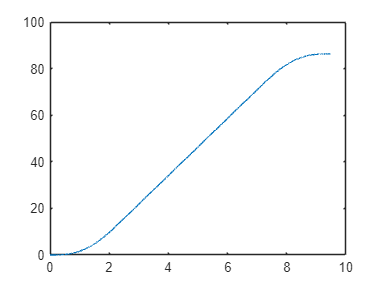

n=1;
v_1=V_s+J*T_1^2/2;
s_1=V_s*T_1+J*T_1^3/6;
v_2=v_1+a_max*T_2;
s_2=s_1+v_1*T_2+a_max*T_2^2/2;
v_3=v_2+a_max*T_3-J*T_3^2/2;
s_3=s_2+v_2*T_3+a_max*T_3^2/2-J*T_3^3/6;
v_4=v_3;
s_4=s_3+v_4*T_4;
v_5=v_4-0.5*J*T_5^2;
s_5=s_4+v_4*T_5-J*T_5^3/6;
v_6=v_5-a_max*T_6;
s_6=s_5+v_5*T_6-a_max*T_6^2/2;
for t_0= 0:0.001:T
    if t_0>=0&&t_0<=T_1
        t=t_0;
        s_current(n,:)=V_s*t+J*t^3/6;
        v_current(n,:)=V_s+J*t^2/2;   
        a(n,:)=J*t;
    elseif t_0>T_1&&t_0<=(T_2+T_1)
        t=t_0-T_1;
        s_current(n,:)=s_1+v_1*t+0.5*a_max*t^2;
        v_current(n,:)=v_1+a_max*t;
        a(n,:)=a_max;
    elseif t_0>T_2+T_1&&t_0<=T_3+T_2+T_1
        t=t_0-T_2-T_1;
        s_current(n,:)=s_2+v_2*t+0.5*a_max*t^2-1/6*J*t^3;
        v_current(n,:)=v_2+a_max*t-J*t^2/2;
        a(n,:)=a_max-J*t;
    elseif t_0>T_3+T_2+T_1&&t_0<=T_4+T_3+T_2+T_1
         t=t_0-T_3-T_2-T_1;
        s_current(n,:)=s_3+v_3*t;
        v_current(n,:)=v_3;
        a(n,:)=0;
    elseif t_0>T_4+T_3+T_2+T_1&&t_0<=T_5+T_4+T_3+T_2+T_1
        t=t_0-T_4-T_3-T_2-T_1;
        s_current(n,:)=s_4+v_4*t-J*t^3/6;
        v_current(n,:)=v_4-J*t^2/2;
        a(n,:)=-J*t;
    elseif t_0>T_5+T_4+T_3+T_2+T_1&&t_0<=T_6+T_5+T_4+T_3+T_2+T_1
        t=t_0-T_5-T_4-T_3-T_2-T_1;
        s_current(n,:)=s_5+v_5*t-a_max*t^2/2;
        v_current(n,:)=v_5-a_max*t;
        a(n,:)=-a_max;
    elseif t_0>T_6+T_5+T_4+T_3+T_2+T_1&&t_0<=T
        t=t_0-T_6-T_5-T_4-T_3-T_2-T_1;
        s_current(n,:)=s_6+v_6*t-a_max*t^2/2+J*t^3/6;
        v_current(n,:)=v_6-a_max*t+J*t^2/2;
        a(n,:)=-a_max+J*t;
    end
    n=n+1;
end
t= 0:0.001:T;
plot(t,s_current')

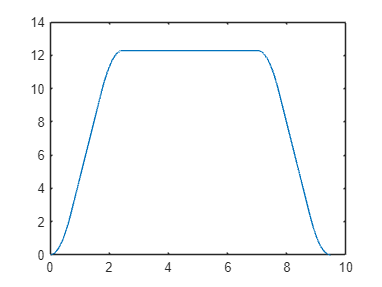

plot(t,v_current')

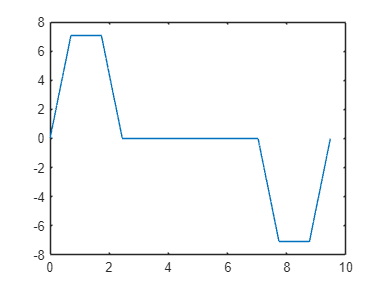

plot(t,a')